# **Environment MPPT Creation**

## Set up de Environment

Speedup Options

useFastRestart = true;
useGPU = true;
useParallel = true;
USE_PRE_TRAINED_MODEL = true; % Set to true, to use pre-trained model
oldAgentName = "agent_DQN_003_250.mat"; % Specify the pre-trained model
%agent_DQN_003_250
%agent_DQN_8000_dif_dD_10
N_panels = 3;
run('VariablesBuck_paneles');

Cin = 8.1164e-05

Cin = 1.0000e-04

L = 1.9470e-05

L = 2.0000e-05

Cout = 1.0856e-04

Cout = 1.1000e-04

Observation info

numObs = 3;
observationInfo = rlNumericSpec([numObs 1]);
observationInfo.Name = 'observation';

Create the action information

actionInfo = rlFiniteSetSpec([-0.03 -0.02 -0.01 0 0.01 0.02 0.03]); %
actioInfo.Name = 'action';

Environment Information

mdl = 'SIM300kW_3paneles'; %% environment
open_system(mdl);
load_system(mdl);
blk = [mdl, '/RL Agent']; % name of agent block
env = rlSimulinkEnv(mdl, blk, observationInfo, actionInfo);
env.ResetFcn = @(in) localResetFcn_3paneles(in, mdl);

## Create Networks

RL parameters

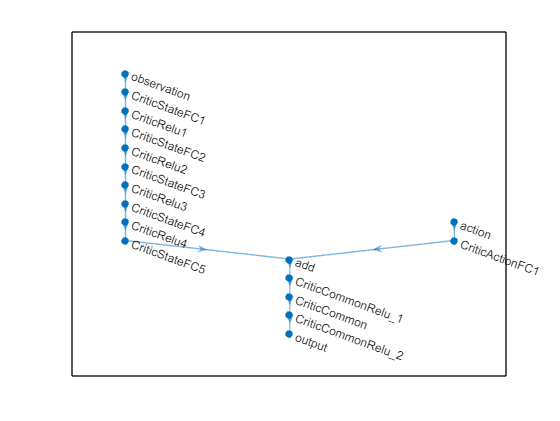

%RL parameters
Ts = 0.02; % Agent sample time
Tf = 0.5;    % Simulation end time
createDQNNetworks; %creating the critic network
figure
plot(criticNetwork)

device = "gpu";
criticOptions = rlRepresentationOptions('Optimizer','adam','LearnRate',0.001, 'UseDevice', device, 'GradientThreshold',1);
obsInfo = getObservationInfo(env);
actInfo = getActionInfo(env);
critic = rlQValueRepresentation(criticNetwork,obsInfo,actInfo,...
    'Observation',{'observation'},'Action',{'action'},criticOptions);

DQN Agent Options

GainReward = 7;
GainDutyPenalty = -1;
maxEpisodes = 5000;

agentOptions = rlDQNAgentOptions;
agentOptions.ResetExperienceBufferBeforeTraining = not(USE_PRE_TRAINED_MODEL);
agentOptions.SampleTime = Ts;
agentOptions.DiscountFactor = 0.9;
agentOptions.MiniBatchSize = 512;
agentOptions.ExperienceBufferLength = 150000;
agentOptions.EpsilonGreedyExploration.Epsilon = 1;
agentOptions.EpsilonGreedyExploration.EpsilonMin = 0.001;
agentOptions.TargetSmoothFactor = 1e-03
agentOptions.EpsilonGreedyExploration.EpsilonDecay = 0.00008%000007%0.000022;

agentOptions =   rlDQNAgentOptions with properties:

                           UseDoubleDQN: 1
               EpsilonGreedyExploration: [1×1 rl.option.EpsilonGreedyExploration]
                 CriticOptimizerOptions: [1×1 rl.option.rlOptimizerOptions]
                     TargetSmoothFactor: 1.0000e-03
                  TargetUpdateFrequency: 1
    ResetExperienceBufferBeforeTraining: 0
                         SequenceLength: 1
                          MiniBatchSize: 512
                    NumStepsToLookAhead: 1
                 ExperienceBufferLength: 150000
                             SampleTime: 0.0200
                         DiscountFactor: 0.9000
                             InfoToSave: [1×1 struct]


agentOptions.UseDoubleDQN = true;
if USE_PRE_TRAINED_MODEL
    curDir = pwd;
    saveDir = 'savedAgents';
    cd(saveDir);
    load(oldAgentName, 'agentObj');
    cd(curDir);
    agentObj.AgentOptions.EpsilonGreedyExploration.Epsilon = 0.65;
    agentOptions.EpsilonGreedyExploration.EpsilonMin = 0.001;
else
    agentObj = rlDQNAgent(critic,agentOptions);
end


## Training Options

trainingOptions = rlTrainingOptions;
trainingOptions.MaxEpisodes = maxEpisodes;
trainingOptions.MaxStepsPerEpisode = round(Tf/Ts);
trainingOptions.ScoreAveragingWindowLength = 56; % the number of episodes included in an average
trainingOptions.StopTrainingCriteria = 'AverageReward';
trainingOptions.StopTrainingValue = 10000;
trainingOptions.SaveAgentCriteria = 'EpisodeReward';
trainingOptions.SaveAgentValue = 150;
trainingOptions.SaveAgentDirectory = pwd + "savedAgents";
trainingOptions.Plots = 'training-progress';
trainingOptions.Verbose = false;
trainingOptions.UseParallel = useParallel;
if useParallel
    trainingOptions.Parallelization = 'async';
    trainingOptions.ParallelizationOptions.StepsUntilDataIsSent = 32;
    trainingOptions.Verbose = true;
end

trainingResults = train(agentObj,env,trainingOptions)

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 5).


Analyzing and transferring files to the workers ...done.
Analyzing and transferring files to the workers ...done.
Episode:   1/5000 | Episode reward:    17.88 | Episode steps:   25 | Average reward:    17.88 | Step Count:   25 | Episode Q0:     7.89
Episode:   2/5000 | Episode reward:    37.40 | Episode steps:   25 | Average reward:    27.64 | Step Count:   50 | Episode Q0:     7.89
Episode:   3/5000 | Episode reward:    25.98 | Episode steps:   25 | Average reward:    27.09 | Step Count:   75 | Episode Q0:     7.88
Episode:   4/5000 | Episode reward:     6.92 | Episode steps:   25 | Average reward:    22.04 | Step Count:  100 | Episode Q0:     7.89
Episode:   5/5000 | Episode reward:     6.81 | Episode steps:   25 | Average reward:    19.00 | Step Count:  125 | Episode Q0:     7.89
Episode:   6/5000 | Episode reward:    19.89 | Episode steps:   25 | Average reward:    19.14 | Step Count:  150 | Episode Q0:     7.89
Episode:   7/5000 | Episode reward:    17.22 | Episode steps:   25 | A

trainingResults =   rlTrainingResult with properties:

       EpisodeIndex: [232×1 double]
      EpisodeReward: [232×1 double]
       EpisodeSteps: [232×1 double]
      AverageReward: [232×1 double]
    TotalAgentSteps: [232×1 double]
       AverageSteps: [232×1 double]
          EpisodeQ0: [232×1 double]
     SimulationInfo: [232×1 Simulink.SimulationOutput]
    TrainingOptions: [1×1 rl.option.rlTrainingOptions]


% 

## Save Results

%% SAVE AGENT
%reset(agentObj); % Clears the experiencbuffer
curDir = pwd;
saveDir = 'savedAgents';
cd(saveDir)
save('agent_DQN_003_250_1','agentObj');
save('trainingResults_DQN_003_250_1','trainingResults');
cd(curDir)
